clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
WindData=data.WindData;
FWT=data.FWT;
G=[FWT(1,1) FWT(1,2)];
%G=tf(G);
Gd = FWT(1,3);
s = tf('s');

wB1=0.3*2*pi; % desired closed-loop bandwidth
A=1/10000 % desired disturbance attenuation inside bandwidth

A = 1.0000e-04

M=3 ; % desired bound on hinfnorm(S)
Wp11=tf([1/sqrt(M) (2*wB1)/sqrt(M) wB1^2],[1 2*wB1*sqrt(A) A*wB1*wB1])

Wp11 =
 
  0.5774 s^2 + 2.177 s + 3.553
  ----------------------------
   s^2 + 0.0377 s + 0.0003553
 
Continuous-time transfer function.



%Wp11=(((s/sqrt(M))+wB1)^2)/((s+(wB1*sqrt(A)))^2)
Wp=[Wp11]; %
%Sensitivity weight
%tau11 = 0.1;
tau22 = 100;
k2 = 0.001;
a1=1

a1 = 10


tau11= 0.1;
%tau21 = 10;
k1 = 1000;

Wu22 = a1*(1/k2)*((tau22*k2*s+1)/(tau22*s+1))  %lead lag filter

Wu22 =
 
  1000 s + 10000
  --------------
    100 s + 1
 
Continuous-time transfer function.



Wu11 = ((k1*tau11*s+1)/(tau11*s+1)) %lead lag filter

Wu11 =
 
  100 s + 1
  ---------
  0.1 s + 1
 
Continuous-time transfer function.



Wu=[Wu11 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []



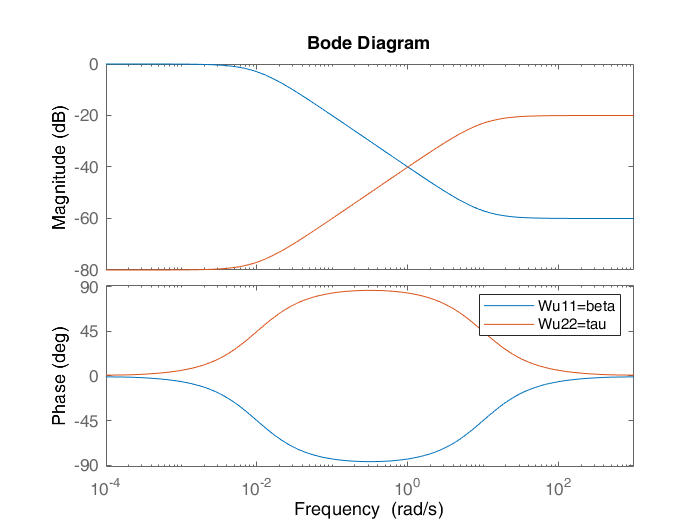

bode(1/Wu11,1/Wu22)
legend({'Wu11=beta','Wu22=tau'})


P11=Wp*Gd;
P12=Wp*-G;
P21=[0;0];
P22=Wu;
P31=Gd;
P32=-G;

P=[P11 P12; P21 P22;P31 P32];
%P=tf(P);
[K,CL,GAM,INFO] = hinfsyn(P,1,2)

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1      -0.0377    -0.02274          16           0           0           0           0
   x2      0.01563           0           0           0           0           0           0
   x3        1.843       11.83       56.26      -35.47       13.09     -0.3175       12.14
   x4      0.08005      0.5141       2.486      -1.542      0.5288     -0.0138      0.5274
   x5            0           0           0           1           0           0           0
   x6       0.5003       3.213       15.54      -9.632       3.555     -0.1915      -7.527
   x7            0           0           0           0           0           1           0
   x8            0           0           0           0           0           0           0
   x9            0           0           0           0           0           0           0
   x10     0.04284      0.2748       1.319     -0.8184      0.3047   -0.00225

GAM = 64.0800

INFO =   hinfINFO with properties:

    gamma: 64.0805
        X: [36×36 double]
        Y: [36×36 double]
       Ku: [2×36 double]
       Kw: [2×36 double]
       Lx: [36×1 double]
       Lu: [2×1 double]
     Preg: [6×4 ss]
       AS: [3×3 ss]


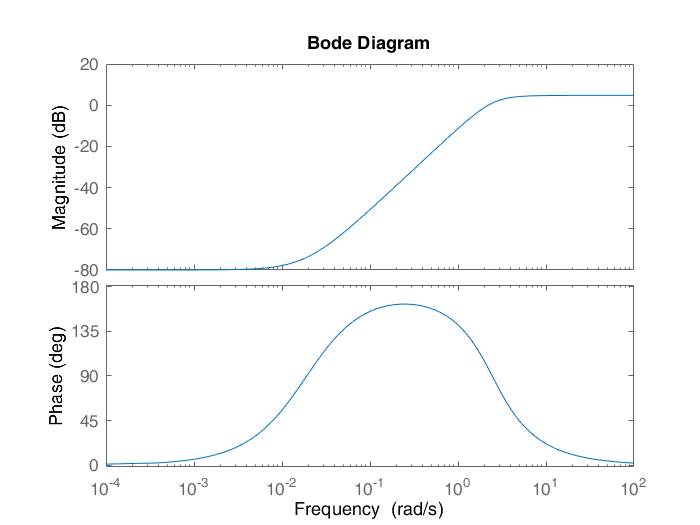


Sens=(1/Wp);
bode(Sens)

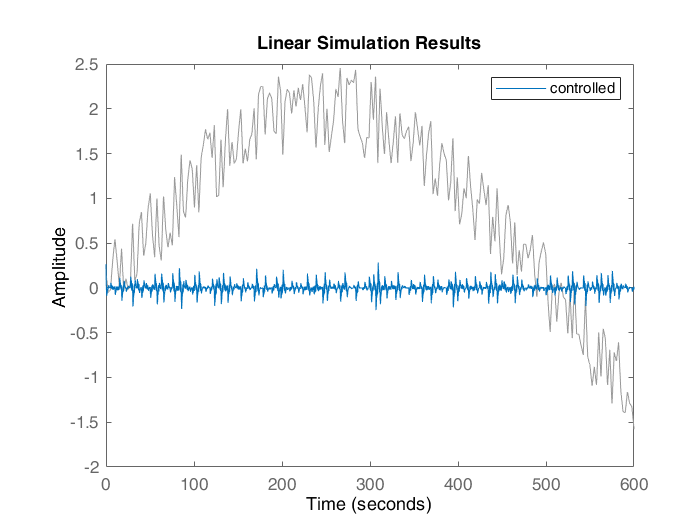


KS1=(1/(Wu11))*CL(2);
KS2=(1/(Wu22))*CL(3);

t = WindData(:,1);
input = WindData(:,2);

figure()
lsim(Sens,input,t)
legend('controlled')

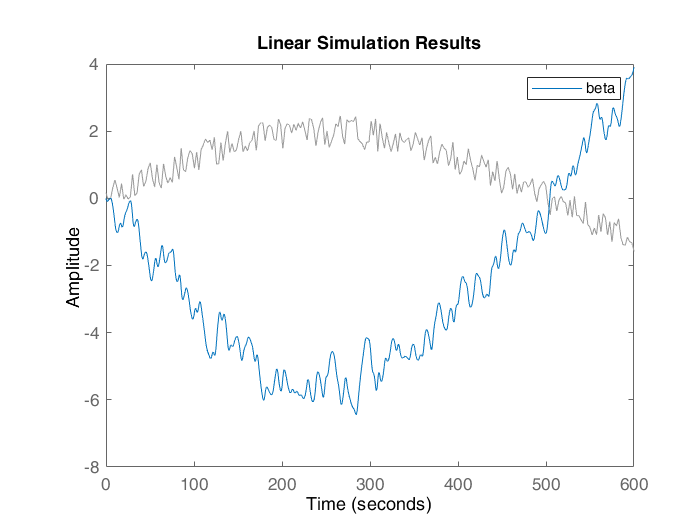


figure()
lsim(KS1,input,t)
legend('beta')

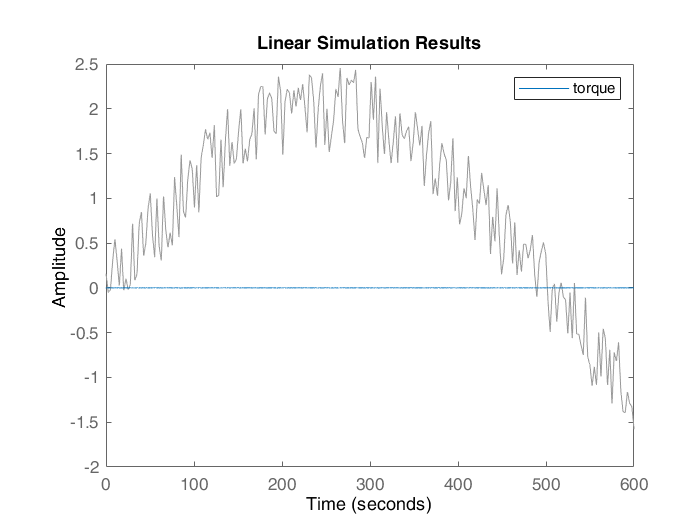


figure()
lsim(KS2,input,t)
legend('torque')


t1 = linspace(0,599,6000);
u1 = sin(2*pi*t1/1000);

% figure()
% 
% subplot(3,1,2)
% lsim(K(1),u1,t1);
% legend('Kbeta')
% subplot(3,1,3)
% lsim(K(2),u1,t1);
% legend('Ktau')
% subplot(3,1,1)
% lsim(Sens,u1,t1);
% legend('S')

